% substituting the values given in the question for M, m1, m2, l1, l2, g

% Now computing the controllability of the system by substituting these
% values into the controllability matrix

Controllability_matrix = [B AB A2_B A3_B A4_B A5_B]

Controllability_matrix = 1.0e-03 *

         0    1.0000         0   -0.1472         0    0.1419
    1.0000         0   -0.1472         0    0.1419         0
         0    0.0500         0   -0.0319         0    0.0227
    0.0500         0   -0.0319         0    0.0227         0
         0    0.1000         0   -0.1128         0    0.1249
    0.1000         0   -0.1128         0    0.1249         0



disp("Checking the the rank of the controllability matrix to check the systems controllability")

Checking the the rank of the controllability matrix to check the systems controllability


disp(rank(Controllability_matrix));

     6



disp("Since the rank of the matrix is 6 which is full rank, hence the system is controllable")

Since the rank of the matrix is 6 which is full rank, hence the system is controllable



disp("choosing the initial condition")

choosing the initial condition


X0 = [0; 0; 10; 0; 15; 0];

% Choosing the values of R and Q which is used to calculate the LQR cost function
R = 0.5;
Q = diag([1, 1, 1, 1, 1, 1])

Q =      1     0     0     0     0     0
     0     1     0     0     0     0
     0     0     1     0     0     0
     0     0     0     1     0     0
     0     0     0     0     1     0
     0     0     0     0     0     1


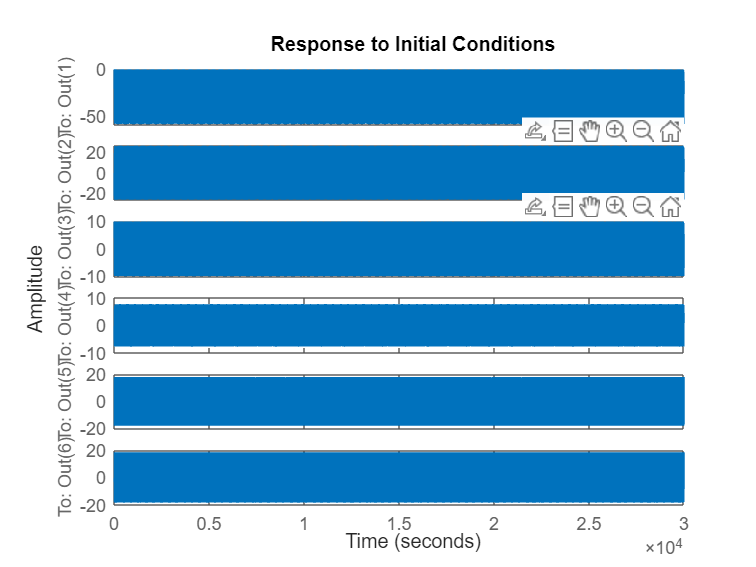


% we know that the D=0
D = 0;

% LQR response for open loop system
openLoopSystem = ss(A,B,C,D);
figure
initial(openLoopSystem,X0)


% Computing Gain matrix(K), Positive definte matrix(P), Eigen values
[K_matrix, P_matrix, EigenValues] = lqr(A,B,Q,R);
K_matrix

K_matrix =     1.4142   58.2683   -2.1316  -92.3217   -1.0675  -46.2364


P_matrix

P_matrix = 1.0e+05 *

    0.0004    0.0085   -0.0007   -0.0141   -0.0003   -0.0071
    0.0085    0.3496   -0.0128   -0.5827   -0.0064   -0.2914
   -0.0007   -0.0128    0.2844    0.0213   -0.0002    0.0106
   -0.0141   -0.5827    0.0213    1.5011    0.0107    0.4609
   -0.0003   -0.0064   -0.0002    0.0107    0.1377    0.0053
   -0.0071   -0.2914    0.0106    0.4609    0.0053    0.3713


EigenValues

EigenValues =   -0.0001 + 0.7285i
  -0.0001 - 0.7285i
  -0.0001 + 1.0430i
  -0.0001 - 1.0430i
  -0.0243 + 0.0243i
  -0.0243 - 0.0243i


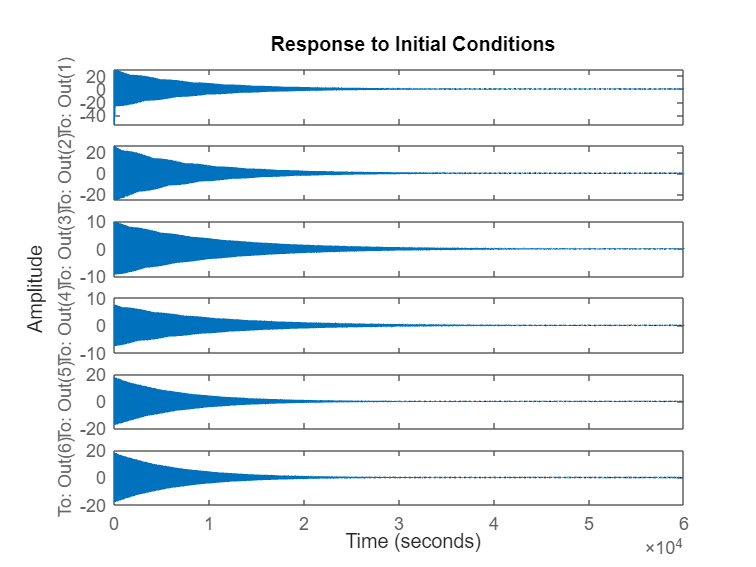

Ac = A-(B*K_matrix);

% LQR response for closed loop system- linear state feedback
closedLoopSystem = ss(Ac,B,C,D);
figure
initial(closedLoopSystem,X0)

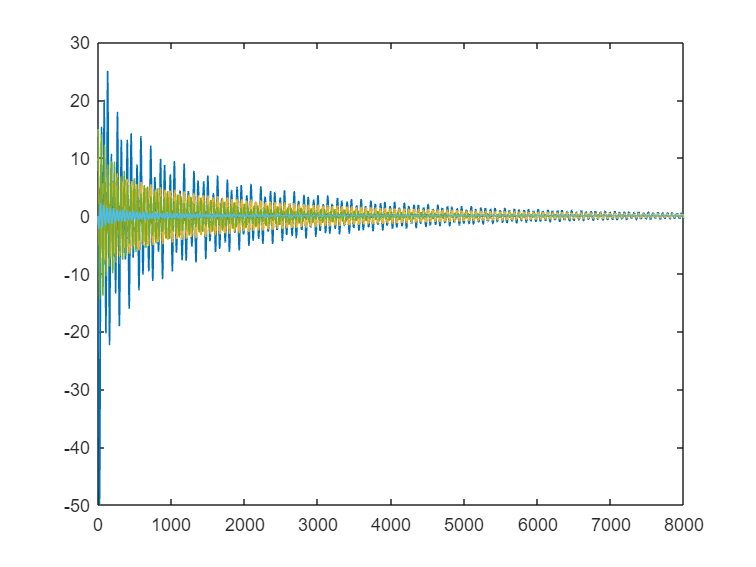


% Non-linear system using LQR controller
Timespan = 0:0.1:8000;
[t1,x1] = ode45(@LQR_controller,Timespan,X0);
% Plot the function output
plot(t1,x1)

function X_dot = LQR_controller(T1,X)
% Given Initial conditions
% Mass of the Crane, mass of load1, mass of load2, Cable length 1,
% Cable length 2, gravity

M= 1000;
m1= 100; 
m2= 100;
l1= 20; 
l2= 10;
g= 9.81;

% A matrix
A=[0 1 0 0 0 0;
0 0 -(m1*g)/M 0 -(m2*g)/M 0;
0 0 0 1 0 0;
0 0 -((M+m1)*g)/(M*l1) 0 -(m2*g)/(M*l1) 0;
0 0 0 0 0 1;
0 0 -(m1*g)/(M*l2) 0 -(g*(M+m2))/(M*l2) 0];

% B matrix
B=[0; 
   1/M;
   0;
   1/(M*l1);
   0;
   1/(M*l2)];

% Choosing the values of R and Q which is used to calculate the LQR cost function
Q = diag([1, 1, 1, 1, 1, 1]);
R = 0.05;
[K_matrix] = lqr(A,B,Q,R);

% Input to the system which is the force
Force = -K_matrix*X;
X_dot = zeros(6,1);

% X_dot
X_dot(1) = X(2); 

% X_Doubledot
X_dot(2)=(Force-(g/2)*(m1*sind(2*X(3))+m2*sind(2*X(5)))-(m1*l1*(X(4)^2)*sind(X(3)))-(m2*l2*(X(6)^2)*sind(X(5))))/(M+m1*((sind(X(3)))^2)+m2*((sind(X(5)))^2)); 

% Theta_1 dot
X_dot(3)= X(4); 

% Theta_1 Doubledot;
X_dot(4)= (X_dot(2)*cosd(X(3))-g*(sind(X(3))))/l1'; 

% Theta_2 Dot
X_dot(5)= X(6); 

% Theta_2 Doubledot;
X_dot(6)= (X_dot(2)*cosd(X(5))-g*(sind(X(5))))/l2; 
end

